# Dam sizing

addpath("utils\")
clc;
% clear all; 
close all;


## Example

q = [1 2 3 3 5 5 8 6 7 3 2 1];

### Ripple method

r = 4;
Rt = r*ones(size(q));
getRipple(Rt,q)

ans = 7

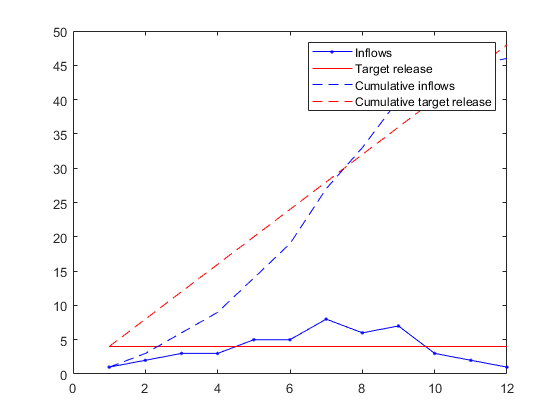

figure;
plot(q, '.-b'); hold on;
plot(Rt, 'r'); hold on;
plot(cumQt, '--b'); hold on;
plot(cumRt, '--r'); hold on;
legend('Inflows', 'Target release', 'Cumulative inflows', 'Cumulative target release')

### Sequent Peak Analysis

Rt = r*ones(size(q));
[spa, K] = getSPA(Rt,q)

spa = 7

K =      0     3     5     6     7     6     5     1     0     0     1     3     6


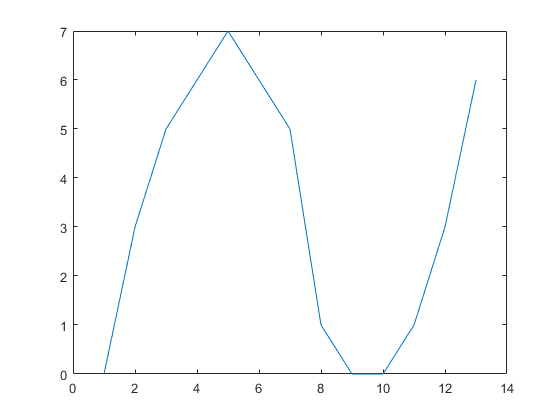


figure;
plot(K)

## Verbano river data

data = load("data\Verbano_inflows_74_83_nb.txt");
Q_month = dailyToMonthly(data, 10);
w = 100; %Target release - Downstream demand
deltaT = 3600*24*[31 28 31 30 31 30 31 31 30 31 30 31]';
Q = Q_month(:).*repmat(deltaT,10,1) ; % m3/month
W = w*ones(size(Q)).*repmat(deltaT,10,1) ; % m3/month

[spa, K] = getSPA(W,Q)

spa = 108907200

K = 	1.0e+08 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


lake_surface = 211500000; % m2
spa/lake_surface

ans = 0.5149

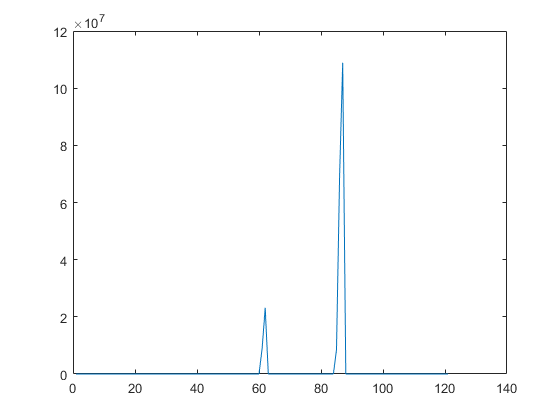

figure;
plot(K)